clear
close all

rng(42)

size_x = 50;
size_y = 40;


mu = 258

mu = 258

background_noise_sigma = 16

background_noise_sigma = 16

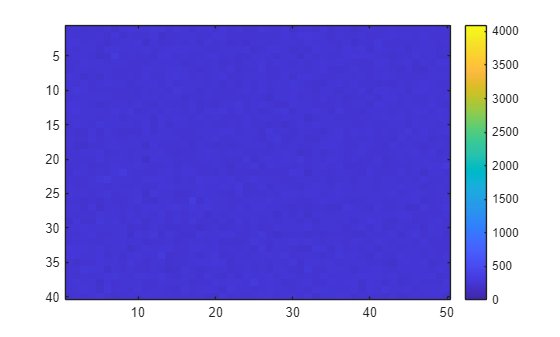


arr = mu + background_noise_sigma.*randn(size_y, size_x);

figure;
imagesc(arr);
colorbar
clim([0,4095])


fprintf('Synthectic background with noise : min : %.2f', min(arr, [], 'all'))

Synthectic background with noise : min : 206.26

fprintf('Synthectic background with noise : max : %.2f', max(arr, [], 'all'))

Synthectic background with noise : max : 326.05

fprintf('Synthectic background with noise : sigma : %.2f', std(arr, [], 'all'))

Synthectic background with noise : sigma : 16.32

fprintf('')

prob = 0.07;

star_mask = rand(size(arr)) < prob;
arr = (1500 + arr).*star_mask + ~star_mask.*arr;

star_mask = rand(size(arr)) < prob;
arr = (2500 + arr).*star_mask + ~star_mask.*arr;

star_mask = rand(size(arr)) < prob;
arr = (3500 + arr).*star_mask + ~star_mask.*arr;




kappa = 3;
max_iter = 20;

## ================= CLASSIC KAPPA-SIGMA CLIPPING =================

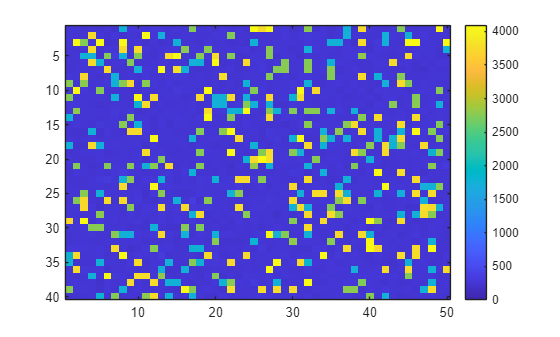

Current iteration: 1

Current min: 206.26

Current max: 7766.66

Current sigma: 1207.29

Current reject threshold: k*sig: 2414.58

Number of rejected values: 0

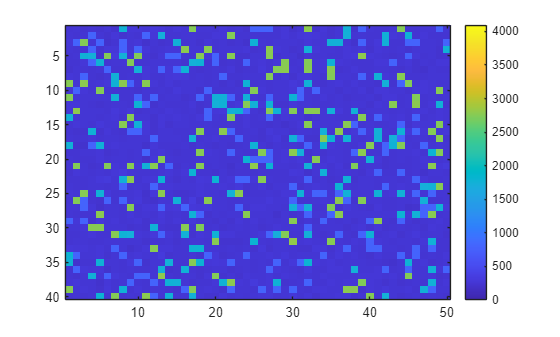

Current iteration: 2

Current min: 206.26

Current max: 2800.34

Current sigma: 686.13

Current reject threshold: k*sig: 1372.27

Number of rejected values: 151

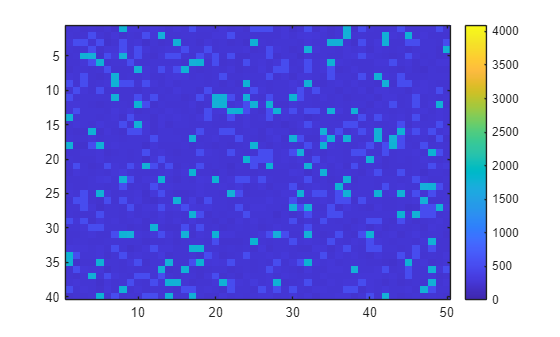

Current iteration: 3

Current min: 206.26

Current max: 1794.03

Current sigma: 389.40

Current reject threshold: k*sig: 778.80

Number of rejected values: 264

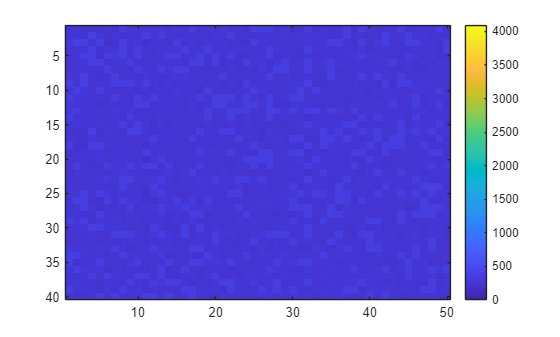

Current iteration: 4

Current min: 206.26

Current max: 326.05

Current sigma: 16.38

Current reject threshold: k*sig: 32.77

Number of rejected values: 390

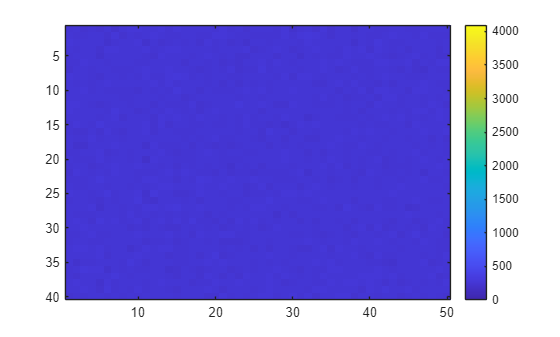

Current iteration: 5

Current min: 206.26

Current max: 290.82

Current sigma: 15.43

Current reject threshold: k*sig: 30.87

Number of rejected values: 423

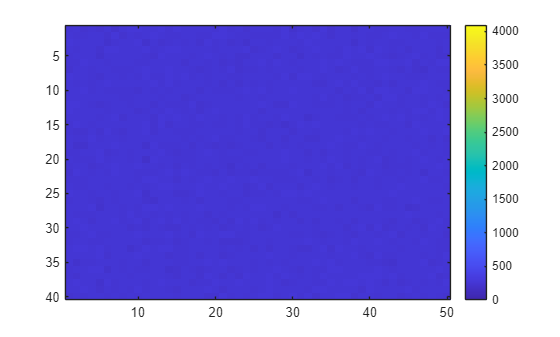

Current iteration: 6

Current min: 206.26

Current max: 287.81

Current sigma: 14.98

Current reject threshold: k*sig: 29.96

Number of rejected values: 449

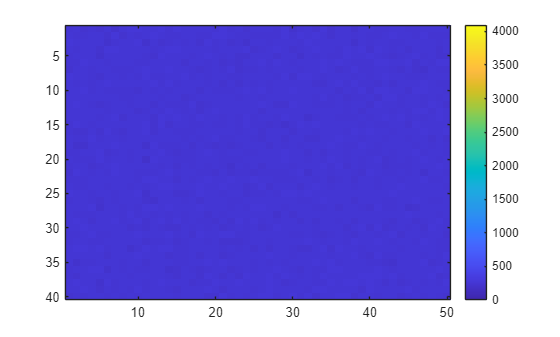

Current iteration: 7

Current min: 206.26

Current max: 286.51

Current sigma: 14.87

Current reject threshold: k*sig: 29.75

Number of rejected values: 456

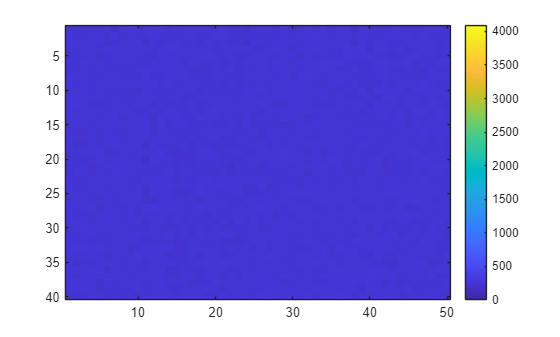

Current iteration: 8

Current min: 206.26

Current max: 286.33

Current sigma: 14.86

Current reject threshold: k*sig: 29.72

Number of rejected values: 457

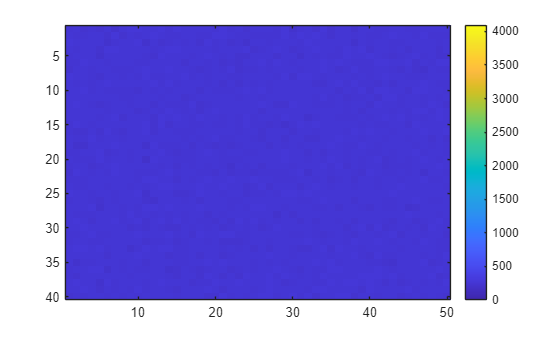

Current iteration: 9

Current min: 206.26

Current max: 286.13

Current sigma: 14.83

Current reject threshold: k*sig: 29.66

Number of rejected values: 459

Iterations to convergence : 9

keep_mask = true(size(arr(:)));
last_keep_mask = keep_mask;
arr_vec = arr(:);
plot_arr = arr_vec;

classic_ksc = tic;
for i = 1:max_iter

    % Replace rejected values with the mean for visualization purposes
    plot_arr(~keep_mask) = mu;
    reconstructed_image = reshape(plot_arr, size_y, size_x);
    figure;
    imagesc(reconstructed_image);
    colorbar
    clim([0,4095])

    arr_kept = arr_vec(keep_mask); % picks the kept elements and converts them to a vector

    mu = mean(arr_kept);
    sig = std(arr_kept);
    
    fprintf('Current iteration: %d', i)
    fprintf('Current min: %.2f', min(arr_kept))
    fprintf('Current max: %.2f', max(arr_kept))
    fprintf('Current sigma: %.2f', sig)
    fprintf('Current reject threshold: k*sig: %.2f', kappa*sig)
    fprintf('Number of rejected values: %d', sum(~keep_mask))
    fprintf('')

    % Update the keep mask effectively excluding the outliers in the next iteration
    keep_mask = (arr_vec - mu) < (kappa*sig);

    if isequal(keep_mask, last_keep_mask)
        fprintf('Iterations to convergence : %d', i)
        classic_iter = i;
        classic_sigma = sig;
        break
    end

    last_keep_mask = keep_mask;

end

classic_ksc_time = toc(classic_ksc);



## ================= ROBUST KAPPA-SIGMA CLIPPING =================

fprintf('\n ROBUST kappa-sigma clipping')


 ROBUST kappa-sigma clipping

Current ROBUST iteration: 1

Current min: 206.26

Current max: 7766.66

Current MAD: 15.10

Current sigma: 22.38

Current reject threshold: k*sig: 44.76

Number of rejected values: 0

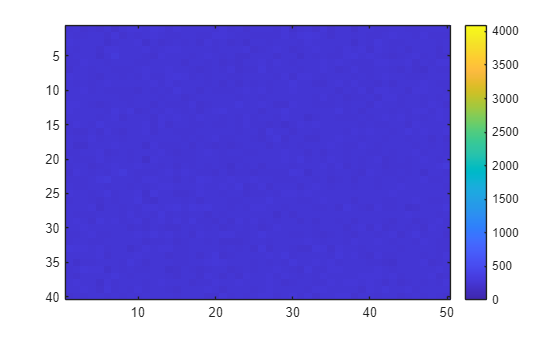

Current ROBUST iteration: 2

Current min: 206.26

Current max: 306.48

Current MAD: 11.20

Current sigma: 16.60

Current reject threshold: k*sig: 33.21

Number of rejected values: 393

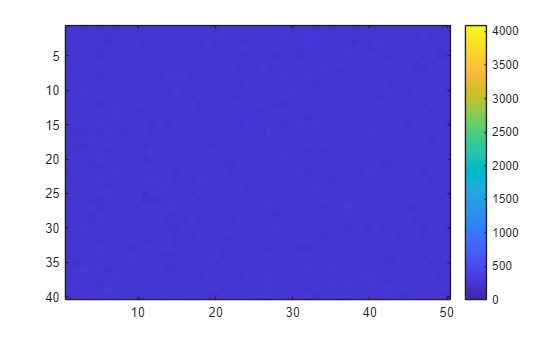

Current ROBUST iteration: 3

Current min: 206.26

Current max: 291.39

Current MAD: 10.86

Current sigma: 16.09

Current reject threshold: k*sig: 32.19

Number of rejected values: 421

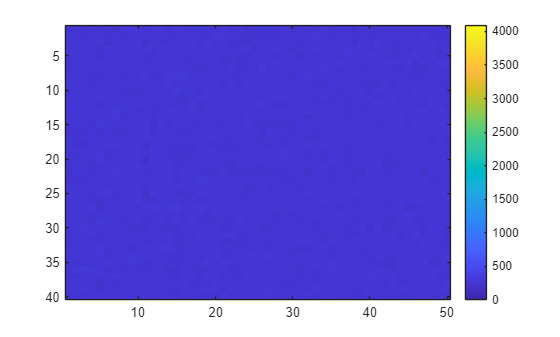

Current ROBUST iteration: 4

Current min: 206.26

Current max: 290.12

Current MAD: 10.79

Current sigma: 15.99

Current reject threshold: k*sig: 31.98

Number of rejected values: 430

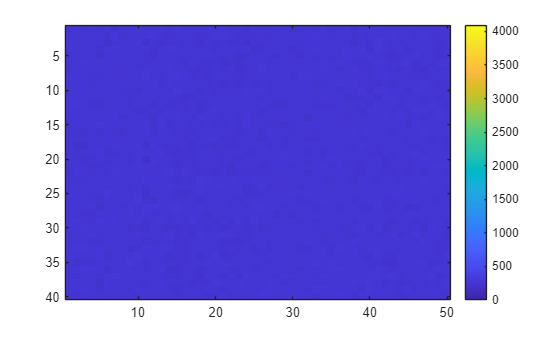

Current ROBUST iteration: 5

Current min: 206.26

Current max: 289.76

Current MAD: 10.78

Current sigma: 15.98

Current reject threshold: k*sig: 31.97

Number of rejected values: 432

Iterations to convergence : 5


keep_mask = true(size(arr(:)));
last_keep_mask = keep_mask;
arr_vec = arr(:);
plot_arr = arr_vec;
med = median(arr_vec);

robust_ksc = tic;
for i = 1:max_iter

    % Replace rejected values with the mean for visualization purposes
    plot_arr(~keep_mask) = med;
    reconstructed_image = reshape(plot_arr, size_y, size_x);
    figure;
    imagesc(reconstructed_image);
    colorbar
    clim([0,4095])

    arr_kept = arr_vec(keep_mask); % picks the kept elements and converts them to a vector

    med = median(arr_kept);
    MAD = median(abs(arr_kept - med));
    sig = 1.4826*MAD;

    fprintf('Current ROBUST iteration: %d', i)
    fprintf('Current min: %.2f', min(arr_kept))
    fprintf('Current max: %.2f', max(arr_kept))
    fprintf('Current MAD: %.2f', MAD)
    fprintf('Current sigma: %.2f', sig)
    fprintf('Current reject threshold: k*sig: %.2f', kappa*sig)
    fprintf('Number of rejected values: %d', sum(~keep_mask))
    fprintf('')

    % Update the keep mask effectively excluding the outliers in the next iteration
    keep_mask = (arr_vec - med) < (kappa*sig);

    if isequal(keep_mask, last_keep_mask)
        fprintf('Iterations to convergence : %d', i)
        robust_iter = i;
        robust_sigma = sig;
        break
    end
    
    last_keep_mask = keep_mask;

end

robust_ksc_time = toc(robust_ksc);




## Final comparison


fprintf('Time for classical Kappa-Sigma Clipping: %.2f', classic_ksc_time)

Time for classical Kappa-Sigma Clipping: 0.53

fprintf('Time for robust Kappa-Sigma Clipping: %.2f', robust_ksc_time)

Time for robust Kappa-Sigma Clipping: 0.31



fprintf('Iterations to convergence : %d', classic_iter)

Iterations to convergence : 9

fprintf('Iterations to convergence : %d', robust_iter)

Iterations to convergence : 5



fprintf('Final sigma : %.2f', classic_sigma)

Final sigma : 14.83

fprintf('Final sigma : %.2f', robust_sigma)

Final sigma : 15.98



robust_speed_gain = classic_ksc_time / robust_ksc_time;
fprintf('Robust Speed Gain Factor: %.2f x\n', robust_speed_gain)

Robust Speed Gain Factor: 1.74 x
